EbN0_db = 0:2:24;
EbN0 = 10.^(EbN0_db/10);

%MPSK
M_PSK = [2, 4, 8, 16, 32];
P_SER_PSK = zeros(length(M_PSK), length(EbN0));

for i = 1:length(M_PSK)
M = M_PSK(i);
P_SER_PSK(i,:) = 2 * qfunc(sqrt(2*EbN0*sin(pi/M)));
end

%MPAM
M_PAM = [2, 4, 8, 16];
P_SER_PAM = zeros(length(M_PAM), length(EbN0));

for i = 1:length(M_PAM)
M = M_PAM(i);
P_SER_PAM(i,:) = 2 *(M-1)/M * qfunc(sqrt(6*log2(M)/(M^2 - 1) * EbN0));
end

%MQAM
M_QAM = [4,16,64,256];
P_SER_QAM = zeros(length(M_QAM), length(EbN0));
for i = 1:length(M_QAM)
M = M_QAM(i);
P_SER_QAM(i,:) = 4 * (1 - 1/sqrt(M)) * qfunc(sqrt(3*log2(M)/(M-1) * EbN0))
end

P_SER_QAM =     0.1573    0.0750    0.0250    0.0048    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_QAM =     0.1573    0.0750    0.0250    0.0048    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5566    0.3902    0.2345    0.1115    0.0370    0.0070    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_QAM =     0.1573    0.0750    0.0250    0.0048    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5566    0.3902    0.2345    0.1115    0.0370    0.0070    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0377    0.8767    0.6946    0.5008    0.3139    0.1592    0.0583    0.0129    0.0013    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_QAM =     0.1573    0.0750    0.0250    0.0048    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5566    0.3902    0.2345    0.1115    0.0370    0.0070    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0377    0.8767    0.6946    0.5008    0.3139    0.1592    0.0583    0.0129    0.0013    0.0000    0.0000    0.0000    0.0000
    1.4231    1.3112    1.1753    1.0134    0.8268    0.6225    0.4162    0.2328    0.0992    0.0278    0.0040    0.0002    0.0000



%MFSK (coherent)
M_MFSK = [2, 4, 8, 16, 32]; % M values for MFSK
P_SER_MFSK_coherent = zeros(length(M_MFSK), length(EbN0));
for i = 1:length(M_MFSK)
M = M_MFSK(i);
P_SER_MFSK_coherent(i, :) = qfunc(sqrt(2*EbN0*log2(M)/(M-1)));
end

%MFSK (non coherent)
P_SER_MFSK_noncoherent = zeros(length(M_MFSK), length(EbN0));
for i = 1:length(M_MFSK)
M = M_MFSK(i);
P_SER_MFSK_noncoherent(i, :) = exp(-(EbN0/2)) .* (((1+EbN0).^(M-1) - 1)./(M-1))
end

P_SER_MFSK_noncoherent =     0.6065    0.7175    0.7154    0.5439    0.2691    0.0674    0.0057    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_MFSK_noncoherent =     0.6065    0.7175    0.7154    0.5439    0.2691    0.0674    0.0057    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.4152    2.4555    4.0170    5.5826    5.5378    2.9872    0.5767    0.0209    0.0001    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_MFSK_noncoherent = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0002    0.0004    0.0006    0.0006    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0011    0.0050    0.0268    0.1485    0.6793    1.8758    1.9923    0.4160    0.0061    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_MFSK_noncoherent = 1.0e+14 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0003    0.0188    0.6039    4.2047    2.1915    0.0168    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0


P_SER_MFSK_noncoherent = 1.0e+40 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0010    0.6278    6.5959    0.0847    0.0000    0.0000


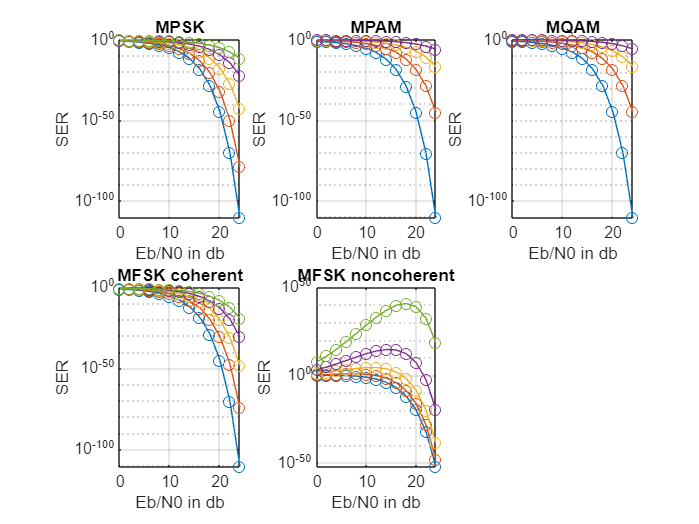


subplot(2,3,1)
for i=1:length(M_PSK)
semilogy(EbN0_db,P_SER_PSK(i,:),'-o'); hold on;
end
title('MPSK');
xlabel('Eb/N0 in db')
ylabel('SER');
grid on;

subplot(2,3,2)
for i=1:length(M_PAM)
semilogy(EbN0_db,P_SER_PAM(i,:),'-o'); hold on;
end
title('MPAM');
xlabel('Eb/N0 in db')
ylabel('SER');
grid on;

subplot(2,3,3)
for i=1:length(M_QAM)
semilogy(EbN0_db,P_SER_QAM(i,:),'-o'); hold on;
end
title('MQAM');
xlabel('Eb/N0 in db')
ylabel('SER');
grid on;

subplot(2,3,4)
for i=1:length(M_MFSK)
semilogy(EbN0_db,P_SER_MFSK_coherent(i,:),'-o'); hold on;
end
title('MFSK coherent');
xlabel('Eb/N0 in db')
ylabel('SER');
grid on;

subplot(2,3,5)
for i=1:length(M_MFSK)
semilogy(EbN0_db,P_SER_MFSK_noncoherent(i,:),'-o'); hold on;
end
title('MFSK noncoherent');
xlabel('Eb/N0 in db')
ylabel('SER');
grid on;